try
    pyenv('Version','C:/Users/tkaneko/anaconda3/envs/openmmlab/python.exe');
catch
end

dtbl=readtable('./labeledGT/valbin2_nanim2_nfrm55/framedata.csv','ReadRowNames',1,'NumHeaderLines',1);
head(dtbl)

                                        Var1                      Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9
                      ________________________________________    ____    ____    ____    ____    ____    ____    ____    ____

    mov10_00235791    {'foodcomp_cj758_cj756_20221207_142242'}    5659    5660    5659    5659    5660    5660    5659    5659
    mov10_00272250    {'foodcomp_cj758_cj756_20221207_142242'}    6534    6535    6535    6534    6535    6534    6534    6534
    mov1_00009750     {'foodcomp_cj711_cj712_20220608_135446'}     234     234     235     235     235     235     234     234
    mov1_00117041     {'foodcomp_cj711_cj712_20220608_135446'}    2809    2809    2810    2810    2810    2810    2809    2809
    mov1_00263916     {'foodcomp_cj711_cj712_20220608_135446'}    6334    6334    6335    6335    6335    6335    6334    6334
    mov2_00000375     {'foodcomp_cj711_cj712_20220817_140511'}      10      10       9       9      10      10

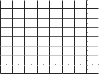

% summary(dtbl)

sessions=unique(dtbl.Var1);

ises=1;
% ises=5;

figure;
haxs=subplot(1,1,1);hold on;
haxss=tight_subplot(8,8,0,0,0);

cnt=0;
allgaps=zeros(1,18);

clear annotKp3ds
clear decodedKp3ds
for ises=1:length(sessions)
    session=sessions{ises};
    flgses=strcmp(dtbl.Var1,session);
    currdtbl=dtbl(flgses,:);



    
    dirPickleRoot='data';
    picklefile=sprintf('%s/%s/kp3d_fxdJointLen.pickle',dirPickleRoot,session);
    if ~exist(picklefile)
     dirPickleRoot2='Z:\kaneko\monkey3d\pipeline\results\3d_v0p329';
    picklefile2=sprintf('%s/%s/kp3d.pickle',dirPickleRoot2,session);
        mkdir(sprintf('%s/%s',dirPickleRoot,session));
        copyfile(picklefile2,picklefile)        
    end 


    fid=py.open(picklefile,'rb');
    data=py.pickle.load(fid);
    data=struct(data);
    kp3d=double(data.kp3d);



    for ifrm=1:height(currdtbl);

        currfrm=round(mean(cell2mat(table2cell(currdtbl(ifrm,2:end)))));
        currfrm=currfrm-24*5;
        if currfrm<1 || currfrm>size(kp3d,2)
        continue
        end 
        cnt=cnt+1;
        frmName=currdtbl(ifrm,:).Row;

        jsondata=readjson(sprintf('./labeledGT/valbin2_nanim2_nfrm55/%s.json',frmName{1}));

        % switch subject
        cmbptr=[1,2,1,2;...
            1,2,2,1];
        for irep=1:2
            annotKp3ds_=cat(3,squeeze(jsondata.keypoints_3d(cmbptr(irep,1),1:18,:)),...
                squeeze(jsondata.keypoints_3d(cmbptr(irep,2),1:18,:)));
            currKp3ds_=cat(3,squeeze(kp3d(cmbptr(irep,3),currfrm,:,:)),...
                squeeze(kp3d(cmbptr(irep,4),currfrm,:,:)));
            tmpvals(irep)=mean(nanmedian(vecnorm((annotKp3ds_-currKp3ds_),2,2)));
        end
        % get subject
        [val,ind]=min(tmpvals);
        irep=ind;
        annotKp3ds(:,:,:,cnt)=cat(3,squeeze(jsondata.keypoints_3d(cmbptr(irep,1),1:18,:)),...
            squeeze(jsondata.keypoints_3d(cmbptr(irep,2),1:18,:)));
        decodedKp3ds(:,:,:,cnt)=cat(3,squeeze(kp3d(cmbptr(irep,3),currfrm,:,:)),...
            squeeze(kp3d(cmbptr(irep,4),currfrm,:,:)));
         minval(cnt)=val;
    end
end

for ianim=1:2
    hfig=figure;
    haxs=subplot(1,1,1);hold on;
    haxss=tight_subplot(7,8,0,0,0);        
    for ifrm=1:48     
        annotKp3d=squeeze(annotKp3ds(:,:,ianim,ifrm));
        currKp3d=squeeze(decodedKp3ds(:,:,ianim,ifrm));
        haxs=haxss(ifrm);
        axes(haxs);
        hold on;
        [hplts, hplt_skpt] = plotMarmo3D(annotKp3d, haxs);
        [hplts, hplt_skpt] = plotMarmo3D(currKp3d, haxs);
        view([10 20]);
    end
end

gapdata=vecnorm((annotKp3ds-decodedKp3ds),2,2);
gapdata=nanmean(gapdata,2);

save('TwoAnimals.mat','annotKp3ds','decodedKp3ds','minval');